# Nominal Stability Analysis of Linear Discrete Time Systems

**Sachin C. Patwardhan*, Anjali P. Deshpande and Sharad Bhartiya* **

(*) Dept. of Chemical Engineering,

 Indian Institute of Technology Bombay, Mumbai 400076 India  

## Introduction

Two primary considerations while designing any controller are closed loop stability and closed loop performance. Controller formulations presented till now consider only the closed loop performance. In the previous lesson, we saw that  solution of infinite horizon LQOC problem gives state feedback control law of the form $u(k)=-G_{\infty }x(k)$. LQOC guarantees desired closed loop performance under the ideal conditions (linear system dynamics). What about the closed loop stability when this controller is used? How do we find out whether this optimal control guarantees stable closed loop behavior?   

**Learning Objectives**

Develop framework for stability analysis of an unforced discrete time linear dynamic system using 

- **Lyapunov's First Method: **Eigenvalues of the state transition matrix 

- **Lyapunov's Second Method:** Using construction of Lyapunov function 

## **Preliminaries**

Let us assume that the system system dynamics are governed by the ideal discrete time linear model

$x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)$   -------------(1)

Together withe the LQOC controller, the closed loop dynamics for this system reduces to 

 $x\left(k+1\right)=\left(\Phi -\Gamma G_{\infty } \right)\;x\left(k\right)$  --------------(2)

which is an unforced dynamic system. 

Thus, it is sufficient to investigate behavior of a generic unforced system of the form $x\left(k+1\right)=\Phi x\left(k\right)$ and then apply our findings to analysis of equation (2). 

In this lesson we investigate behavior of an ideal discrete time linear system 

$x\left(k+1\right)=\Phi x\left(k\right)$    --------------(3) 

 at the equilibrium point of the system which corresponds to the origin of the state space. Here $x\in R^n$ and the autonomous system starts evolving from an arbitrary initial condition$x\left(0\right)$. 

To begin with, we first need to define what we mean by stable dynamic behavior. Let us define two sets in the neighborhood of the origin as follows 


$$B\left(\varepsilon \right)=\left\lbrace x\left(k\right):\|x\left(k\right)\|\le \varepsilon \right\rbrace \;\;\;\;\textrm{and}\;\;\;\;\;B_0 \left(\delta \right)=\left\lbrace x\left(0\right):\;\|x\left(0\right)\|\le \delta \right\rbrace$$


If we use the usual 2-norm, then these sets are simply circles around the origin as shown in Figure 1. 

**Definition: **The equilibrium point is said to be Lyapunov stable, if for every $\varepsilon >0,\textrm{there}\;\textrm{exists}\;a\;\delta >0\;\textrm{such}\;\textrm{that},\textrm{if}\;\left\|x\left(0\right)\|<\delta \;\right.$ implies that $\left\|x\left(k\right)\|<\varepsilon \right.$. Further, the system is said to be asymptotically stable, if it is Lyapunov stable and, in addition, $\left\|x\left(k\right)\right\|\to 0$ as $k\to \infty$. The origin is marginally stable if it is Lyapunov stable but not asymptotically stable. 

The equilibrium point is unstable if it is not Lyapunov stable. 

In simple terms, given any bounded region $B\left(\varepsilon \right)$ in the neighborhood of the origin, if we can find to find a set of initial conditions $B_0 \left(\delta \right)$ such that all state trajectories starting from any point in $B_0 \left(\delta \right)$ remains inside $B\left(\varepsilon \right)$. If these trajectories finally collapse into the origin as the time progresses, then the equilibrium point is asymptotically stable. Figure 1 shows schematic representation of trajectories starting from sets $B_0 \left(\delta \right)$  in $R^2$ under three different scenarios. 

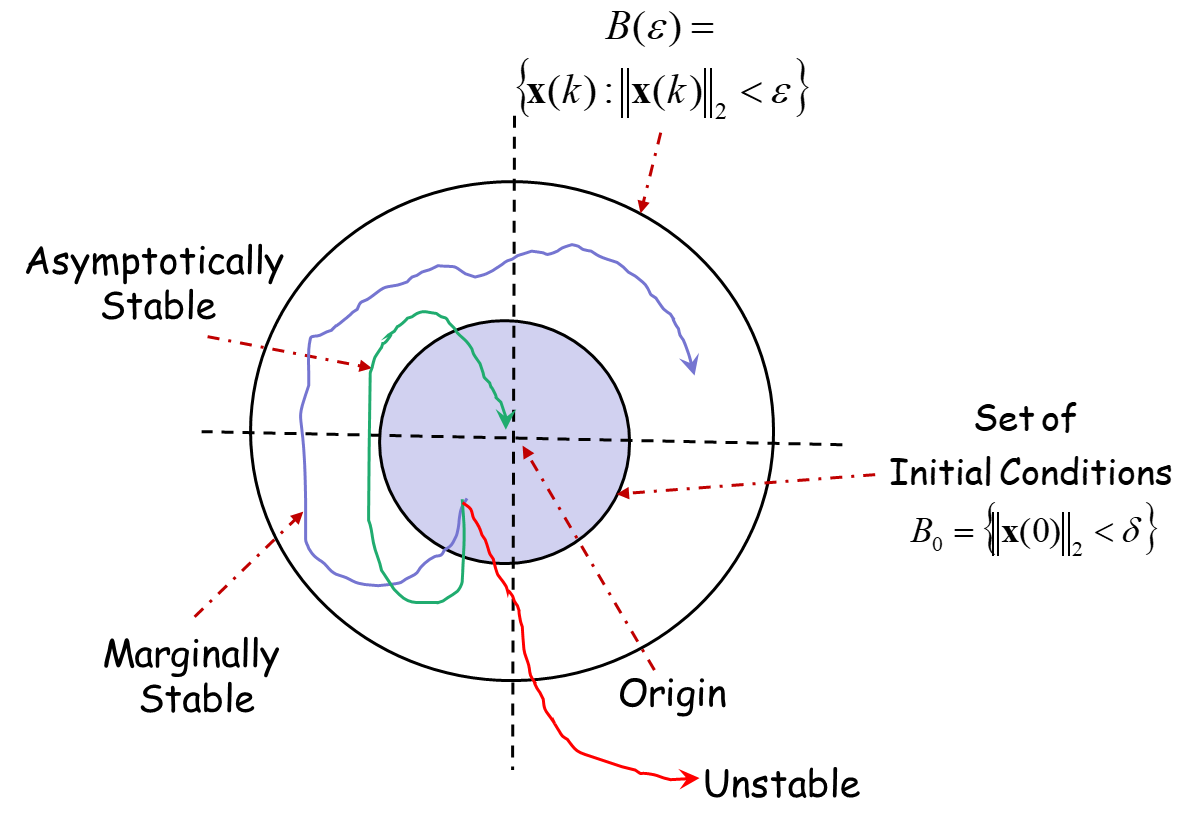

**Figure 1: Schematic representation of sets **$B_0$** and **$B\left(\varepsilon \right)$** in **$R^2$**  and trajectories starting from **$B_0$ 

Lyapunov's first and second methods are used to qualify the equilibrium point as stable, asymptotically stable or unstable. 

## Lyapunov’s First Method 

Consider the unforced response of the system given by equation (3). When the initial condition x(0) is non-zero, the system states evolve according to 

$x\left(k\right)=\Phi^k x\left(0\right)$   ----------(4)

For an arbitrary initial condition, we are interested in finding the asymptotic behavior of the system, i.e. how $\left\|x\left(k\right)\right\|={\|\Phi }^k x\left(0\right)\|\;\;$ as $k\to \infty$. 

Consider a special case where $\Phi$ is diagonalizable matrix and has distinct eigenvalues. Thus, we can factorize $\Phi$ as $\Phi =\Psi \Lambda \Psi^{-1}$,  where $\Lambda$ is a diagonal matrix with eigenvalues of $\Phi$, i.e. $\lambda_i :i=1,2,\ldotp \ldotp \ldotp ,n\;$, appearing as the diagonal elements and columns of $\Psi$ are eigen-vectors of $\Phi$. Using this factorization, we can show that 

 $\Phi =\Psi \Lambda \Psi^{-1} \Rightarrow \Phi^2 =\Psi \Lambda^2 \Psi^{-1} \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \Rightarrow \Phi^k =\Psi \Lambda^k \Psi^{-1}$ -----------(5)

This allows us to express the solution $x\left(k\right)$ as 

$x\left(k\right)=\Phi^k x\left(0\right)=\Psi \Lambda^k \Psi^{-1} x\left(0\right)\;\;\;\;$---------(6)

This expression holds the key to analyzing asymptotic behavior of the dynamics without requiring explicit computations of $\Phi^k$. Since $\Lambda$ is a diagonal matrix, it follows that  


$$\Lambda^k =\left\lbrack \begin{array}{cccc}
\lambda_1^k  & 0 & \ldotp \ldotp  & 0\\
0 & \lambda_2^k  & \ldotp \ldotp  & 0\\
\ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp \\
0 & 0 & \ldotp \ldotp  & \lambda_n^k 
\end{array}\right\rbrack$$
  

As a consequence, behavior of $\lambda_i^k :i=1,2,\ldotp \ldotp \ldotp ,n$ decides the behavior of $\Phi^k$. Let us consider the following cases. 

**Case 1: **All the eigenvalues of  $\Phi$  are in strictly inside the unit circle in complex  λ-plane. Since $\left|\lambda_i \right|<1$ for $i=1,2,\ldotp \ldotp \ldotp n$, it follows that $\lambda_i^k \to 0\;\textrm{as}\;k\to \infty$. This implies that $\Lambda^k \to \left\lbrack 0\right\rbrack \;\textrm{as}\;k\to \infty \;$and $\Phi^k =\Psi \Lambda^k \Psi^{-1} \to \left\lbrack 0\right\rbrack$. Here, [0] represents the null matrix. Thus, it follows that 

$\;\;\|x\left(k\right)\|=\|\Phi^k x\left(0\right)\|\to 0\;\textrm{as}\;k\to \infty$ --------(7)

for any arbitrary $x\left(0\right)$. Thus, any state trajectory $\left\lbrace x\left(k\right):k=0,1,2,\ldotp \ldotp \ldotp \ldotp \right\rbrace$ starting from any $x\left(0\right)$ collapses into the origin as $k\to \infty$. The equilibrium point is **asymptotically stable **in this case. 

**Case 2:  **All the eigenvalues of  $\Phi$ are either inside or on the unit circle in complex λ-plane i.e. $\left|\lambda_i \right|\le 1$ for $i=1,2,\ldotp \ldotp \ldotp n$  

If  $\left|\lambda_j \right|=1$   then  ${{|\lambda }_j }^k |$   remains bounded as $k\to \infty$--------(8a)

If  $\left|\lambda_j \right|<1$   then  ${{|\lambda }_j }^k |\to 0$    as $k\to \infty$-------------------(8b)

This implies that $\|\Phi^k \|=\|\Psi \Lambda^k \Psi^{-1} \|$ remains bounded as $k\to \infty \ldotp$ As a consequence, $\left\|x\left(k\right)\right\|={\|\Phi }^k x\left(0\right)\|\;\;$remains bounded as $k\to \infty$ for any arbitrary $x\left(0\right)$.  The equilibrium point is **Marginally Stable** in this case.

**Case 3:  **If one or more eigenvalues of$\;\Phi$ are located outside the unit circle in complex λ-plane i.e. $\left|\lambda_i \right|>1$ for some values of $i=j$, then that implies that

${{\;|\lambda }_j }^k |\to \infty$   as $k\to \infty$  ------(9)

As a consequence, $\|\Phi^k \|=\|\Psi \Lambda^k \Psi^{-1} \|\to \infty$  as $k\to \infty$for any arbitrary $x\left(0\right)\not= 0$. It follows that it follows that $\left\|x\left(k\right)\right\|={\|\Phi }^k x\left(0\right)\|\;\;$becomes unbounded as $k\to \infty$ unless $x\left(0\right)$ corresponds to the origin. The origin of the state space is **unstable **in this case.

 In fact, defining a vector of coefficients as ${c=\;\Psi }^{-1} x\left(0\right)$, we can express the solution as  

$x\left(k\right)=\Psi \Lambda^k \;\lbrack \Psi^{-1} x\left(0\right)\rbrack =c_1 \lambda_1^k V_1 +c_2 \lambda_2^k V_2 +\ldotp \ldotp \ldotp +c_n \lambda_n^k V_n$-----(10)

where $V_i$ represents the eigenvector of $\;\Phi$ that corresponds to the eigenvalue $\lambda_i$. This expression reveals how different dynamic modes of the system evolve with time. Thus, we are able to predict qualitative nature of the asymptotic behavior of solution of system governed by equation (4) just by examining eigenvalues of $\Phi$ for an arbitrary$x\left(0\right)$. 

Moral of the story is that the eigenvalues of the state transition matrix completely determine the stability characteristic of the discrete time linear system governed by equation (4). While we have considered only diagonalizable matrices for the purpose of simplifying the analysis, qualitatively similar  analysis can be carried out for any $\Phi$ which has repeated eigenvalues. This result is summarized in the following theorem. 

**Theorem 1:**  *The equilibrium point of the linear time-invariant system governed by equation (4) is ****stable**** if and only if all the eigenvalues of matrix *$\Phi$* satisfy  *$\left|\lambda_i \right|\le 1$* and the algebraic and geometric multiplicity of the eigenvalues with absolute value 1 coincide. Moreover, the equilibrium point   is globally asymptotically stable if and only if all the eigenvalues of *$\;\Phi$* are such that *$\left|\lambda_i \right|<1$. 

Here, Algebraic Multiplicity refers to the number of times $\lambda_i$ is repeated and Geometric Multiplicity refers to the dimension of null space of matrix $\lambda_i \mathbf{I}-\Phi$. Proof of this theorem can be found in Bon et al. [4]. 

Recall that we started this lesson for analyzing dynamics of system governed by equation (2). Application of Lyapunov's first method yields the condition that all eigenvalues of $\left(\Phi -\Gamma G_{\infty } \right)$ should be strictly inside the unit circle for the ideal closed loop system to be asymptotically stable. 

### Examples

#### CSTR (continuous stirred tank reactor system)

Consider linear discrete time model of a continuous stirred tank reactor system at two different equilibrium points. At the first equilibrium point, the state transition matrix is  


$$\Phi =\left\lbrack \begin{array}{cc}
0\ldotp 185 & -0\ldotp 01\\
73\ldotp 49 & 1\ldotp 33
\end{array}\right\rbrack$$


**Task 1:** Create a matrix as above and save it in a variable **phy1**

phy1=[0.185 -0.01 ; 73.49 1.33];

**Task 2: **Create a variable **eig_val1** using MATLAB command eig

[`e`](https://in.mathworks.com/help/matlab/ref/eig.html#btgapg5-1-e) `= eig(`[`A`](https://in.mathworks.com/help/matlab/ref/eig.html#btgapg5-1-A)`)` returns a column vector containing the eigenvalues of square matrix `A`

eig_val1 = eig(phy1)

eig_val1 =    0.7575 + 0.6381i
   0.7575 - 0.6381i


**Task 3**:Now check the absolute value of eig_value using command abs and save it in variable abs1

`Y = abs(`[`X`](https://in.mathworks.com/help/matlab/ref/double.abs.html#bucsg6q-1-X)`)` returns the [absolute value](https://in.mathworks.com/help/matlab/ref/double.abs.html#budexws-4) of each element in input `X`.

If `X` is complex, `abs(X)` returns the [complex magnitude](https://in.mathworks.com/help/matlab/ref/double.abs.html#budexws-5).

abs1=abs(eig_val1)

abs1 =     0.9904
    0.9904


 Note that both the eigenvalues lie inside the unit circle as $|\lambda_1 |=|\lambda_2 |=0\ldotp 9904$ and the equilibrium point is unstable.  

2. At the second equilibrium point, the state transition matrix is 


$$\Phi =\left\lbrack \begin{array}{cc}
0\ldotp 7943 & -0\ldotp 006245\\
11\ldotp 93 & 1\ldotp 256
\end{array}\right\rbrack$$


 We repeat Tasks 1, 2 and 3 with this new** phy2** matrix. Name the variables as **phy2, eig_val2 and abs2**.

phy2=[0.7943 -0.006245 ; 11.93 1.256]; 
eig_val2 = eig(phy2)

eig_val2 =    1.0252 + 0.1456i
   1.0252 - 0.1456i


abs2=abs(eig_val2)

abs2 =     1.0354
    1.0354


. Note that both the eigenvalues lie outside the unit circle as $|\lambda_1 |=|\lambda_2 |=1\ldotp 0353$ and the equilibrium point is unstable.  

####  Quadruple Tank System 

For the linear model (non-minimum phase system) discretized with sampling time of 4 seconds, the state transition matrix is 


$$\Phi =\left\lbrack \begin{array}{cccc}
0\ldotp 9387 & 0 & 0\ldotp 094 & 0\\
0 & 0\ldotp 958 & 0 & 0\ldotp 06542\\
0 & 0 & 0\ldotp 9029 & 0\\
0 & 0 & 0 & 0\ldotp 9331
\end{array}\right\rbrack$$
 

We repeat Tasks 1, 2 and 3 by creating a this new** phy** matrix. Name the variables as **phy3, eig_val3 and abs3**.

phy3=[0.9387 0 0.094 0; 0 0.958 0  0.06542; 0 0 0.9029 0; 0 0  0 0.9331];
eig_val3 = eig(phy3)

eig_val3 =     0.9387
    0.9580
    0.9029
    0.9331


abs(eig_val3)

ans =     0.9387
    0.9580
    0.9029
    0.9331


`Note that all the eigenvalues are inside unit circle and hence the system is stable. `

#### Quadruple Tank System under LQOC

 Now let un consider the closed loop dynamics with the [LQOC controller designed in the previous lesson](matlab:open('./L01_Linear_Quadratic_Optimal_Controller.mlx')) for the quadruple tank system 


$$G_{\infty } =\left\lbrack \begin{array}{cccc}
2\ldotp 5700 & 0\ldotp 01130 & 0\ldotp 1929 & 0\ldotp 8245\\
0\ldotp 01025 & 2\ldotp 8543 & 1\ldotp 2399 & 0\ldotp 1351
\end{array}\right\rbrack$$


**Task 4:** The $\Phi$ matrix for Q tank is already created and saved as phy3. Now we create $\Gamma$ matrix as follows and name the variable as **gama**

         
$$\Gamma =\left\lbrack \begin{array}{cc}
0\ldotp 3225 & 0\ldotp 0155\\
0\ldotp 0078 & 0\ldotp 2458\\
0 & 0\ldotp 1756\\
0\ldotp 1169 & 0
\end{array}\right\rbrack$$


gama = [0.3225 0.0155; 0.0078 0.2458 ; 0 0.1756 ; 0.1169 0]

gama =     0.3225    0.0155
    0.0078    0.2458
         0    0.1756
    0.1169         0


**Task 5: **We now create a variable **G_inf as a **$2\times 4$ matrix for matrix $G_{\infty }$

G_inf =[2.5700 0.01130 0.1929 0.8245; 0.01025 2.8543 1.2399 0.1351]

G_inf =     2.5700    0.0113    0.1929    0.8245
    0.0103    2.8543    1.2399    0.1351


**Task 6:** We now calculate  the closed loop eigen values for a matrix of $\Phi -\Gamma G$ and save in a variable** eig_val_cl**

eig_val_cl = eig(phy3 - gama * G_inf)

eig_val_cl =    -0.0056
    0.0419
    0.9601
    0.8915


**Task 7**:Now check the absolute value of **eig_val_cl** using command abs and save it in variable **abs_cl.**

abs_cl=abs(eig_val_cl) 

abs_cl =     0.0056
    0.0419
    0.9601
    0.8915


It is clear that the eigenvalues of $\left(\Phi -\Gamma G_{\infty } \right)$ are strictly inside the unit circle in this case and the resulting closed loop system is asymptotically stable. 

## Lyapunov’s Second Method 

**Lyapunov’s Second Method** is a powerful technique to investigate stability characteristics of equilibrium points of dynamical systems. A more detailed exposure to this technique will be later presented in Module 10. In this lesson, however, we provide an introduction to Lyapunov's second method in the context of linear discrete time systems governed by equation (4). Instead of solving the system dynamic equations explicitly, this approach involves construction of a scalar function,$V\left(x\right)$, called as **Lyapunov function** that behaves like an "energy" function. 

**Lyapunov function: **Consider discrete linear system governed by equation (4) together with equilibrium point at the origin of the state space. A scalar function $V\left(x\right):R^n \to R$ represents a Lyapunov function for this system if the following conditions are satisfied: 

- $V\left(x\right)$ is continuous in $\left(x\right)$ and $V\left(0\right)=0$.

- $V\left(x\right)$ is positive definite function of of $x$ i.e. $V\left(x\right)>0$ whenever $x\not= \bar{0}$

- $\Delta V\left(x\left(k\right)\right)=V\left\lbrack x\left(k+1\right)\right\rbrack -V\left\lbrack x\left(k\right)\right\rbrack$  is a negative semi-definite function for all k.

The following result are stated here without proof. Sketch of the proof of this result for more general case can be found in Module 10. 

**Theorem 2:** *The origin of the linear discrete dynamic system governed by equation (4) is ****stable**** if there exists a Lyapunov function, *$V\left(x\right)$*, for the system. Further, if  *$\Delta V\left(x\right)$* is strictly *

***-ve ****definite at every point  except at the origin, then the origin is globally asymptotically stable. *

 Consider a candidate Lyapunov function for the linear $x\left(k+1\right)=\Phi x\left(k\right)$ defined as follows 

$V\left(x\left(k\right)\right)={x\left(k\right)}^T P\;x\left(k\right)$ ------(11)

where P is a** +ve** definite matrix. We can find $\Delta V\left(x\left(k\right)\right)$ as 


$$V\left(x\left(k+1\right)\right)={x\left(k+1\right)}^T P\;x\left(k+1\right)={x\left(k\right)}^T \Phi^T P\;\Phi \;x\left(k\right)$$


$\Delta V\left(x\left(k\right)\right)=V\left\lbrack x\left(k+1\right)\right\rbrack -V\left\lbrack x\left(k\right)\right\rbrack$ = ${x\left(k\right)}^T \left\lbrack {\;\Phi }^T P\;\Phi -P\right\rbrack \;x\left(k\right)$ ------(12)

Thus, if these exists a positive definite matrix $Q$ such that 

$\left\lbrack {\;\Phi }^T P\;\Phi -P\right\rbrack =-Q$ ------(13) 

then $V\left(x\left(k\right)\right)$ is a Lyapunov function for the linear system. Equation (13) is called as the Lyapunov equation. The following  theorem connects Lyapunov’s first and second method. 

***Theorem 3: ****Matrix *$\Phi$ *has all the eigenvalues strictly inside the unit circle, if and only if, for any arbitrary ****+ve**** definite matrix *$Q$,* there exists ****+ve**** definite matrix *$P$* such that satisfies the Lyapunov equation (12). Moreover ****P**** is a unique solution of the Lyapunov equation. *

Proof of this theorem can be found in Bon et al. [4]. 

### Examples

- **CSTR**

Consider linear discrete time model of a continuous stirred tank reactor system at the stable equilibrium point. At the first equilibrium point, the state transition matrix is  


$$\Phi =\left\lbrack \begin{array}{cc}
0\ldotp 185 & -0\ldotp 01\\
73\ldotp 49 & 1\ldotp 33
\end{array}\right\rbrack$$


Eigenvalues of $\Phi$ are $\lambda_1 =0\ldotp 7575+0\ldotp 6381i\;\textrm{and}\;\lambda_2 =0\ldotp 7575-0\ldotp 6381$. Both the eigenvalues lie inside the unit circle as $|\lambda_1 |=|\lambda_2 |=0\ldotp 9904$ and the equilibrium point is stable. 

phy=[0.185 -0.01 ; 73.49 1.33]; 
eig(phy)

ans =    0.7575 + 0.6381i
   0.7575 - 0.6381i


Q = 0.1 * eye(2) ;  % specify Q matrix

[**dlyap**](https://in.mathworks.com/help/control/ref/dlyap.html) command in MATLAB is used to find the solution of Discrete time Lyapunov equation.

disp('Solution of Discrete Time Lyapunov Equation')

Solution of Discrete Time Lyapunov Equation


P = dlyap(phy',Q)  % Discrete time Lyapunov equation solution 

P = 1.0e+04 *

    3.4482    0.0272
    0.0272    0.0005


disp('eigenvalues of P')

eigenvalues of P


eig(P)

ans = 1.0e+04 *

    0.0003
    3.4484


Note that eigenvalues of $P$ are positive. If you change $Q$ to some other +ve definite matrix, you will find the $P$ matrix found by solving discrete Lyapunov equation is always +ve definite in this case. 

2.**  Quadruple Tank System:** 

For the linear model (non-minimum phase system) discretized with sampling time of 4 seconds, eigenvalues of the state transition matrix are strictly inside the unit circle. Thus, a unique solution must exist for the discrete Lyapunov equation for arbitrary +ve definite Q matrix. 

We have set $Q=10*\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$

phy=[0.9387 0 0.094 0; 0 0.958 0  0.06542; 0 0 0.9029 0; 0 0  0 0.9331];
disp('Eigen values of phy')

Eigen values of phy


eig(phy)

ans =     0.9387
    0.9580
    0.9029
    0.9331


Q = 10 * eye(4) ;  % specify Q matrix
P = dlyap(phy',Q)  % Discrete time Lyapunov equation solution 

P =    84.1451         0   48.7038         0
         0  121.6012         0   71.8354
   48.7038         0  102.8878         0
         0   71.8354         0  149.1643


Eigen values of P 

eig(P)

ans =    43.9193
   62.2373
  143.1136
  208.5283


As can be expected from Theorem 3, since eigenvalues of $\Phi$ are positive, the discrete Lyapunov equation will generate a +ve definite solution for any +ve definite $Q$ matrix. 

## Nominal Stability Analysis of LQR

**Nominal stability analysis** refers to analyzing the stability of a system **under its nominal (ideal or expected) conditions**, i.e., **without considering uncertainties**, disturbances, or modeling errors. This is the baseline analysis that tells you whether your system, as designed or modeled, is stable. The stability of a **Linear Quadratic (LQ) controller **typically referring to the **Linear Quadratic Regulator (LQR)**—is a well-established property, but it depends on certain assumptions, such as a perfect linear time invariant(LTI) system. 

**Theorem: **(Stability of the closed loop system) Consider the time invariant system given by equation

$x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)$------------(14)

and the loss function for the optimal control is given by equation

 $J=∑_{k=0}^{N-1}[x(k)^{T}W_{x}x(k)+u(k)^{T}W_{u}u(k)]+x(N)^{T}W_{N}x(N) $----------(15)

Assume that a positive-definite steady state solution $S_{\infty }$ exists for Riccati equation 

$S_{\infty }=[\Phi -\Gamma G_{\infty }]^{T}S_{\infty }[\Phi -\Gamma G_{\infty }]+W_{x}+G_{\infty }^{T}W_{u}G_{\infty } $. -----------(16)

Then, the steady state optimal strategy

$u(k)=-G_{\infty }x(k)=-[W_{u}+\Gamma ^{T}S_{\infty }\Gamma ]⁻¹\Gamma ^{T}S_{\infty }\Phi x(k)$------------(17)

gives an asymptotically stable closed-loop system

$x(k+1)=(\Phi -\Gamma G_{\infty })x(k)$----------------(18)

**Proof: ** To prove asymptotic stability, it is sufficient to show that for the function

$V\left(x\left(k\right)\right)=x^T \left(k\right)S_{\infty } x\left(k\right)$-----------(19)

$S_{\infty }$ is **+ve** definite

 $\Delta V\left(x\left(k\right)\right)$ is strictly -ve definite. Since  $S_{\infty }$ is +ve definite, $V\left(x\left(k\right)\right)$ is positive definite and


$$\bigtriangleup V(x(k))  = x^{T}(k+1)S_{\infty }x(k+1)-x^{T}(k)S_{\infty }x(k)$$



$$= x^{T}(k)(\Phi -\Gamma G_{\infty })^{T}S_{\infty }(\Phi -\Gamma G_{\infty })x(k)-x^{T}(k)S_{\infty }x(k)$$


	$= -x^{T}(k)[W_{x}+G_{\infty }^{T}W_{u}G_{\infty }]x(k)$-----------(20)

This follows from the ARE  that

$\bigtriangleup V(x(k))=-x^{T}(k)[W_{x}+G_{\infty }^{T}W_{u}G_{\infty }]x(k)$--------(21)

Because  $W_{x}+G_{\infty }^{T}W_{u}G_{\infty }$ is positive definite, $\Delta V$ is strictly negative definite. 

Thus, the closed loop system is asymptotically stable for any choice of  **positive definite **$W_{x} $  and **positive semi-definite  **$W_{u}.$

The poles of the closed loop system can be obtained in several ways. When the design is completed, the poles are obtained from

$det(\lambda I-\Phi +\Gamma G_{\infty })=0$--------------(22)

It is possible to show that the poles are the n stable eigenvalues of the generalized eigenvalue problem. 

$\left\lbrack \begin{array}{cc}
I & 0\\
W_x  & \Phi^T 
\end{array}\right\rbrack \lambda -\left\lbrack \begin{array}{cc}
\Phi  & \Gamma {W_u }^T \Gamma \\
0 & I
\end{array}\right\rbrack =0$-------------(23)

This equation is called the Euler equation of the LQ problem. Theorem 1 shows that LQ controller gives a stable closed loop system, i.e. all poles of  $\Phi -\Gamma G_{\infty } $ are strictly inside unit circle. Thus, a LQ  optimal controller guarantees performance as well as asymptotic stability under the nominal conditions.

## Conclusion

In this lesson we have seen how the stability of linear discrete time systems is determined using eigenvalue analysis (Lyapunov's first method) and using construction of Lyapunov function (Lyapunov's second method).  We have learnt that the asymptotic dynamic behavior of a discrete linear model is completely determined by the eigenvalues of the state transition matrix. Moreover, if the origin of the discrete time system is asymptotically stable, then we can always construct a Lyapunov function for the system. Subsequently, these important results have been used to analyze closed loop stability when LQOC is used to control the system. It is shown that, under the ideal/nominal conditions, i.e. the plant is linear time invariant and the model matrices are perfectly known, linear quadratic optimal control provides a method to guarantee closed loop performance and stability simultaneously. For LQ Controller

- Guaranteed closed loop performance and stability for **any reachable **system

- Relationship between the design parameters and closed loop performance is transparent

**Advantages of LQOC**

- In a Linear quadratic optimal controller can be expressed in infinite and fixed horizon optimization formulation. The design procedure (i.e. solving discrete ARE) automatically guarantees the nominal closed loop stability.   

- By selecting **Wx **and **Wu** appropriately, it is easy to compromise between speed of recovery and magnitude of control signals. Selecting weighting matrices in the objective function is relatively easy than directly selecting closed loop poles. Relationship between the weighting matrices and the closed loop performance is transparent.  

- It can be used for an open loop stable or marginally stable or unstable system as long as the system is reachable 

**Limitations of LQOC**

- Difficult to incorporate operating constraints explicitly 

- Limits on manipulated inputs / rate of change of manipulated inputs 

- Limits of process outputs (arising from product quality, safety considerations) 

- Algebraic Riccati Equations: AREs is notoriously difficult to solve for large dimensional systems 

These difficulties can be systematically handled in the [Model Predictive Control](matlab:open('../5. MPC_Plain_Vanilla_Version/L1_LQOC_To_MPC.mlx')).

## References

Astrom, K. J., and B. Wittenmark, Computer Controlled Systems, Prentice Hall India (1994).

Franklin : Franklin, G. F. and J. D. Powell, Digital Control of Dynamic Systems, Addison-Wesley, 1989.

Goodwin : Goodwin, G., Graebe, S. F., Salgado, M. E., Control System Design, Phi Learning, 2009.

Khalil, H. K., Nonlinear Systems (3’rd Ed.), Prentice Hall, 2002. 

Luenberger, D. G., Introduction to Dynamic Systems, John Wiley, 1979. 

Bof, N., Carli, R., Schenato, R., Lyapunov Theory for Discrete Time Systems, Technical Report, Universita degli studi di Padova, Italy, 2017. 

Fadali, M. S. And Visioli, A., Digital Control Engineering: Analysis and Design, Academic Press, 2019. 

Trentelman, H. (2013). Linear Quadratic Optimal Control. In: Baillieul, J., Samad, T. (eds) Encyclopedia of Systems and Control. Springer, London. https://doi.org/10.1007/978-1-4471-5102-9_201-3